Implement a function to visualize the Carrol barrier’s effect used in inequality constrained optimization problems for functions of two variables. The input should be the objective function f , the constraints g, and the parameter ρ. The function should create a 3D plot of the original and the scaled objective functions. Provide some samples with bounded feasible regions (e.g. triangle, rectangle, circle or some other nice region of your choice).

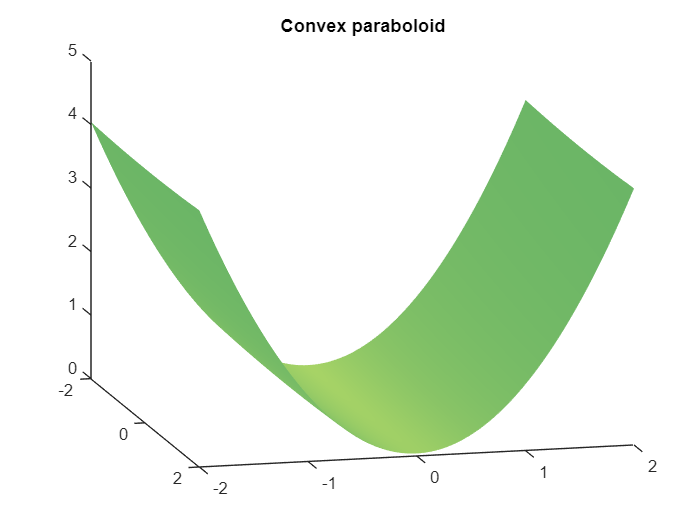

% convex paraboloid(s)
% recommended region: [-2,2]x[-2,2]
aa = 0.01;
f=@(x) aa.*x(1).^2+x(2).^2;

% ellipsoid
el = @(x,c,a,b) (x(1)-c(1))^2/a.^2 + (x(2)-c(2))^2/b.^2 - 1;

% objective function plotting
X = linspace(-2,2,256);
Y = linspace(-2,2,256);
[X,Y] = meshgrid(X,Y);
Z = zeros(256,256);
for i=1:256
    for j=1:256
        Z(i,j) = f([X(i,j),Y(i,j)]);
    end
end
figure; hold on;
surfl(X,Y,Z);
colormap("summer");
shading interp;
title("Convex paraboloid");
view([76 16]);
hold off;

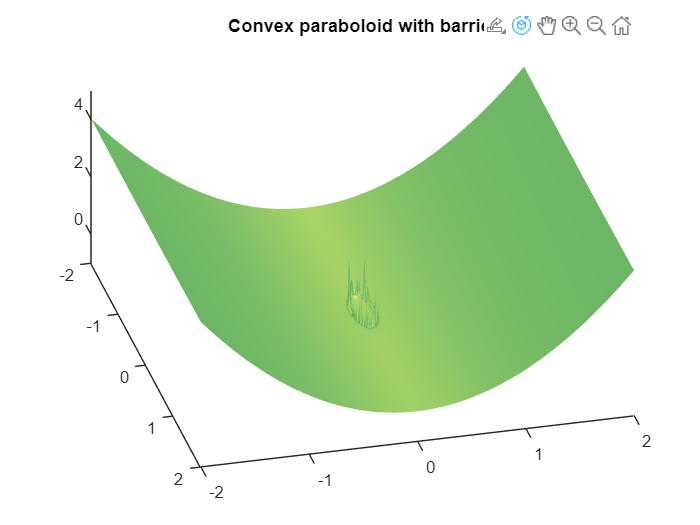


c = [0; 0]; % center of ellipsoid
a = 0.3; % semi-major axis
b = 0.1; % semi-minor axis
rho = 200;

% objective function with barrier plotting
Z = zeros(256,256);
for i=1:256
    for j=1:256
        Z(i,j) = f([X(i,j),Y(i,j)]) + 1/rho * Carrol_barrier(el, [X(i,j),Y(i,j)], c, a, b);
    end
end
figure; hold on;
surfl(X,Y,Z);
colormap("summer");
shading interp;
title("Convex paraboloid with barrier");
zlim([-1;5]);
view([76 16]);
hold off;

function elx = Carrol_barrier(g, x, c, a, b)
    elx = -sum(1./g(x,c,a,b));
end